%Instability condition
u = 30;
D = 0.2;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt +1;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx +1;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

T = zeros(n_step_space,n_step_time);

% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
for i = 2:n_step_space-1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end


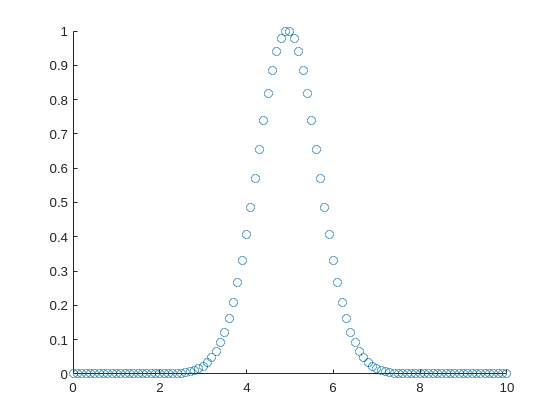

scatter(x, T(:,1))

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (4*(alpha^2) < 2*beta && 2*beta < 1)
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability not respected!


% i indice per lo spazio
% j indice per il tempo
for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;
    end
end

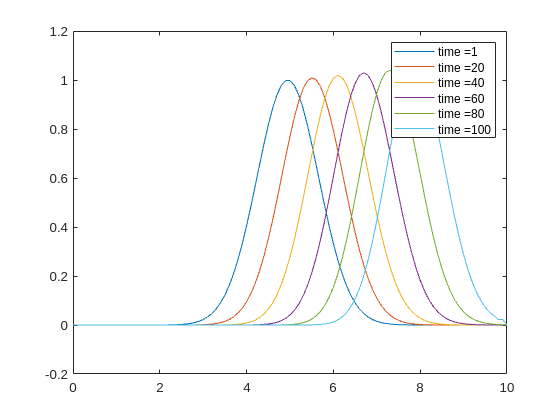

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*20));
end

plot(x, T(1:n_step_space, 1))
hold on
for j = 1:5
    plot(x, T(1:n_step_space,(j)*20));
    hold on
end
legend(Legend)
hold off

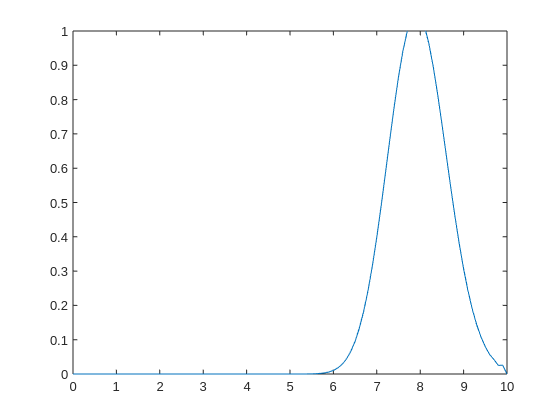

for j = 1:n_step_time
    plot(x, T(:,j))
    ylim([0,1])
    pause (0.1)
end

%Stable conditions but with spike
u = 30;
D = 4;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt +1 ;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx +1 ;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

T = zeros(n_step_space,n_step_time);

% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
for i = 2:n_step_space-1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end


scatter(x, T(:,1))

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (4*(alpha^2) < 2*beta && 2*beta < 1)
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability respected!


% i indice per lo spazio
% j indice per il tempo
for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;
    end

    %Spike
    if (j == 35)
        T(75, j) = 1;
    end
end

clear legend

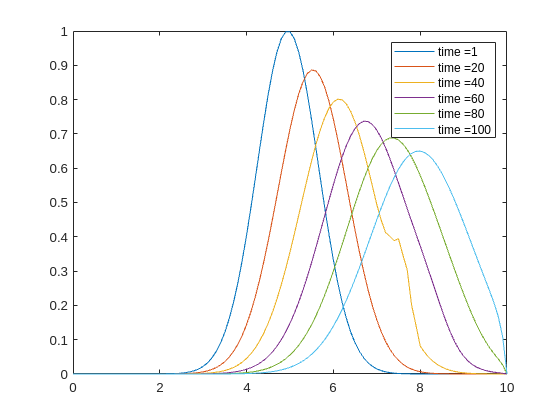

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*20));
end

plot(x, T(1:n_step_space, 1))
hold on
for j = 1:5
    plot(x, T(1:n_step_space,(j)*20));
    hold on
end
legend(Legend)
hold off
legend(Legend)
hold off

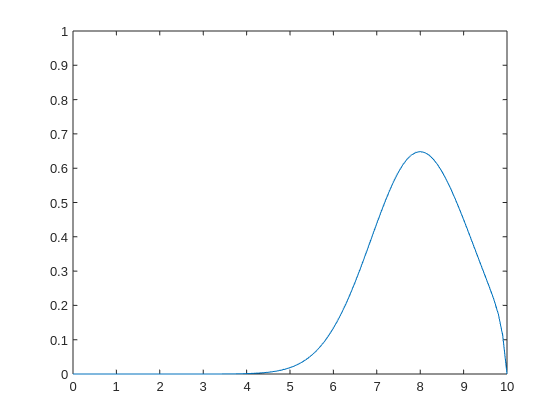

for j = 1:n_step_time
    plot(x, T(:,j))
    ylim([0,1])
    pause (0.1)
end

%Unstable conditions but with spike
u = 30;
D = 0.2;

t_start = 0;

t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt +1 ;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx +1 ;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

T = zeros(n_step_space,n_step_time);

% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
for i = 2:n_step_space-1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end


scatter(x, T(:,1))

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (4*(alpha^2) < 2*beta && 2*beta < 1)
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability not respected!


% i indice per lo spazio
% j indice per il tempo
for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;
    end

    %Spike
    if (j == 35)
        T(75, j) = 1;
    end
end

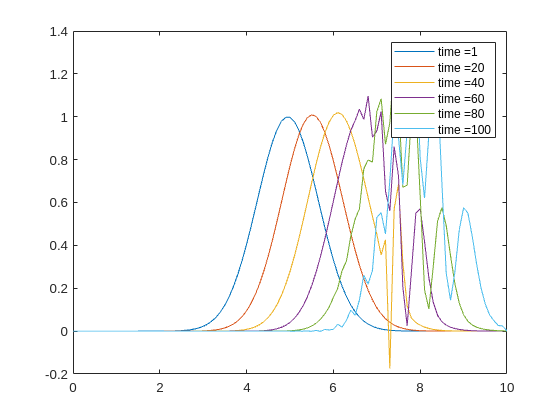

clear legend
Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*20));
end

plot(x, T(1:n_step_space, 1))
hold on
for j = 1:5
    plot(x, T(1:n_step_space,(j)*20));
    hold on
end
legend(Legend)
hold off

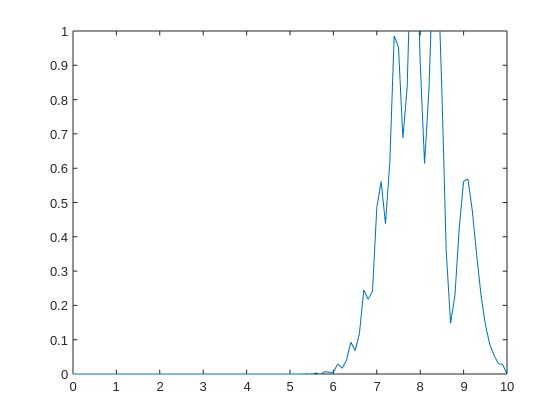

for j = 1:n_step_time
    plot(x, T(:,j))
    ylim([0,1])
    pause (0.1)
end